# Dinamica Letterale Veicolo Autobilanciato - gruppo Calegari

clear
clc

syms t; % tempo
syms T; % Energia cinetica del sistema
syms U; % Energia potenziale del sistema
syms alpha; % Angolo di offset statico che sposta in avanti il baricentro
syms beta; % Altro angolo statico, vedi disegno
syms l_c l_a l_b m_a m_c m_r m_b g r;
syms J_r J_b J_a J_c;
syms q_1 q_1_p q_1_pp;
syms q_2 q_2_p q_2_pp;
syms C_m; % Coppia motrice
syms tau;
syms s;

% Coordinate libere
syms phi(t); % Angolo letto dagli encoder
vel = diff(phi, t); %velocità carello
syms theta(t); % angolo inclinazione
vel_ang = diff(theta, t);%vel angolare
syms q_1 q_1_p q_2 q_2_p;

## Calcolo componenti dinamiche e potenziali per ogni corpo rigido del sistema

Per il calcolo delle equazioni dinamiche del sistema siamo andati a considerare ogni singolo corpo rigido componente il sistema, calcolandone le grandezze fisiche di posizione e velocità, con un approccio cartesiano. 

Nello specifico abbiamo considerato il sistema composto da:

- Asta ($P_a$)

- Utente a bordo dello chassis ($P_c$)

- Chassis (o base) ($P_b$)

- Ruota ($P_r$) che poi sarà considerata con un contributo doppio, essendo 2 le ruote del sistema

Per ognuno di questi corpi rigidi siamo andati appunto a calcolare:

- Coordinate spaziali nel sistema di riferimento XZ, con l'aggiunta delle coordinate angolari $$\rightarrow$$ vettore 3 x 1

- Vettore delle velocità $$\rightarrow$$ vettore 3 x 1

- Matrice delle masse $$\rightarrow$$ matrice 3 x 3

- Energia cinetica dello specifico corpo rigido $$\rightarrow$$ $T=\frac{1}{2\;}\bullet V^T \bullet M\bullet V$

- Energia potenziale dello specifico corpo rigido$$\rightarrow$$ $U$

- Lagrangiana dello specifico corpo rigido $$\rightarrow$$ $L=T-U$

### Asta $P_a$

P_a = [phi*r+l_a*sin(theta+beta); l_a*cos(theta+beta); theta]
V_a = diff(P_a, t)
M_a = [m_a,0,0; 0,m_a,0; 0,0,J_a + m_a *l_a^2] % Matrice delle masse/inerzie
T_a = collect(simplify((1/2 * transpose(V_a) * M_a * V_a), 'Steps', 50))
U_a = m_a * g * l_a * cos(theta+beta);
L_a = collect(simplify((T_a - U_a), 'Steps', 50));

### Utente  $P_c$

P_c = [phi*r+l_c*sin(theta+alpha); l_c*cos(theta+alpha); theta + alpha]
V_c = diff(P_c,t)
M_c = [m_c,0,0; 0,m_c,0; 0,0,J_c + m_c * l_c^2]
T_c = collect(simplify((1/2 * transpose(V_c) * M_c * V_c), 'Steps', 50))
U_c = m_c * g * l_c * cos(alpha+theta);
L_c = collect(simplify((T_c - U_c), 'Steps', 50))

### Chassis (o base)  $P_b$

Come da specifiche, il baricentro della base risulta essere posizionato ad una quota differente rispetto al centro del sistema di coordinate preso come riferimento. Per questo motivo che il suo contributo cinetico e potenziale dipende da quale inclinazione presenta lo chassis stesso, ovvero dall'angolo caratteristico del sistema $\theta \;$. Questo fatto è messo in evidenza nell'immagine seguente:

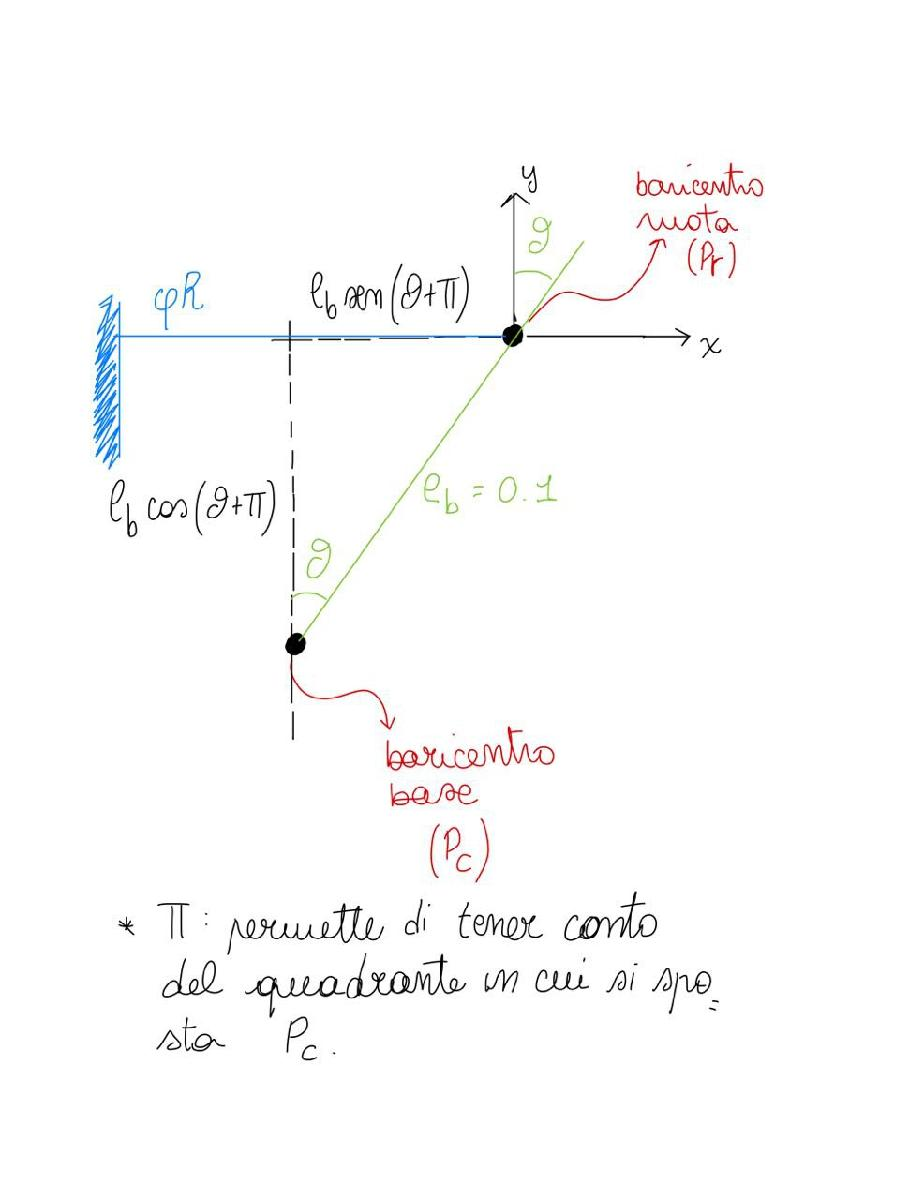

P_b = [phi*r + l_b*sin(pi+theta); l_b*cos(pi+theta); theta]
V_b = diff(P_b,t)
M_b = [m_b,0,0; 0,m_b,0; 0,0,J_b + m_b*l_b^2]
T_b = collect(simplify((1/2 * transpose(V_b) * M_b * V_b), 'Steps', 50))
U_b = m_b * g * l_b * cos(pi+theta);
L_b = collect(simplify((T_b - U_b), 'Steps', 50))

### Ruota $P_r$

P_r = [phi*r; 0; phi]
V_r = diff(P_r,t)
M_r = [m_r,0,0; 0,m_r,0; 0,0,J_r]
T_r = collect(simplify((1/2 * transpose(V_r) * M_r * V_r), 'Steps', 50))
U_r = 0;
L_r = collect(simplify((T_r - U_r), 'Steps', 50))

### Lagrangiana dell'intero sistema

Per confronto, andiamo a definire in prima battuata l'energia cinetica e potenziale totale dell'intero sistema:

T_totale = collect(simplify((T_a + T_b + T_c + 2 * T_r), 'Steps', 50))
U_totale = simplify((U_a + U_b + U_c + 2 * U_r), 'Steps', 50)

Andiamo ora a sommare tutte le singole lagrangiane dei vari corpi rigidi (considerando doppio l'apporto delle ruote).

L = collect(simplify((2*L_r + L_c+ L_a + L_b), 'Steps', 50))
L_q = subs(L,{phi,vel,theta,vel_ang},{q_1 q_1_p q_2 q_2_p}) % Esprimo la Lagrangiana rispetto ai simboli di coordinate libere generiche (q_1 etc)

## Equazioni del moto

Calcoliamo ora le equazioni del moto, considerando, come coordinate libere

- 
$$\phi =q_{1\;} =\textrm{angolo}\;\textrm{di}\;\textrm{rotazione}\;\textrm{delle}\;\textrm{ruote}$$


- 
$$\theta =q_2 =\textrm{inclinazione}\;\textrm{chassis}$$


Utilizziamo questa formulazione:


$$\frac{d}{\textrm{dt}}\left(\frac{\partial }{\partial \dot{q} }L\right)-\frac{\partial }{\partial q}L=\textrm{torque}\;$$


### Calcolo equazioni del moto rispetto a phi ($$q_1$$$=\phi \;$) 

dL_dq1 = diff(L_q,q_1);
dL_dphi = subs(dL_dq1,{q_1 q_1_p q_2 q_2_p},{phi,vel,theta,vel_ang});

dL_dq1p = diff(L_q,q_1_p);
dL_dvel = subs(dL_dq1p,{q_1 q_1_p q_2 q_2_p},{phi,vel,theta,vel_ang});
dL_dvel_dt = diff(dL_dvel,t);
C_m_star = 1/tau*C_m
E_L_phi = collect(simplify((dL_dvel_dt - dL_dphi == -C_m_star), 'Steps', 50))

### Calcolo equazioni del moto rispetto a theta ($q_2$$=\theta \;$) 

dL_dq2 = diff(L_q,q_2);
dL_dtheta = subs(dL_dq2,{q_1 q_1_p q_2 q_2_p},{phi,vel,theta,vel_ang});

dL_dq2p = diff(L_q,q_2_p);
dL_dvel_ang = subs(dL_dq2p,{q_1 q_1_p q_2 q_2_p},{phi,vel,theta,vel_ang});
dL_dvel_ang_dt = diff(dL_dvel_ang,t);

E_L_theta = collect(simplify((dL_dvel_ang_dt - dL_dtheta ==  C_m), 'Steps', 50))

## Risoluzione delle equazioni del moto

Risolviamo ora le due equazioni del moto, ottenendo le variabili $\;\overset{\ldotp \ldotp }{\phi \;}$e $\overset{\ldotp \ldotp }{\theta \;}$.

acc_ang = diff(theta, t, 2);
acc = diff(phi, t, 2);

eqns = [subs(E_L_theta, {acc,acc_ang},{q_1_pp,q_2_pp}), subs(E_L_phi, {acc,acc_ang},{q_1_pp,q_2_pp})];

%To ensure the order of the returned solutions, specify the variables vars. 
%For example, the call [b,a] = solve(eqns,b,a) assigns the solutions for a to a and the solutions for b to b.
S = solve(eqns, q_1_pp, q_2_pp)
phi2 = S.q_1_pp
theta2 = S.q_2_pp

Le due seguenti equazioni simboliche rappresentano le **equazioni non lineari del modello dinamico.**

syms u_star
theta2_differenziabile = subs(theta2,{phi,vel,theta,vel_ang,C_m},{q_1 q_1_p q_2 q_2_p u})
phi2_differenziabile = subs(phi2,{phi,vel,theta,vel_ang,C_m},{q_1 q_1_p q_2 q_2_p u })

## Linearizzazione delle equazioni

Avrò 2 equilibri per l'angolo theta

- 0 --> equilibrio instabile

- k + $\pi \;$ --> equilibrio stabile

`Question ?? : l'equilibrio instabile dell'angolo theta, essendo presente l'asta spostata di un cert valore in avanti, risulterà essere diverso da 0°. Come possiamo porci nei confronti di questo offset sull'equilibrio? Andiamo a linearizzare intorno a questo equilibrio (in cui quindi per l'angolo `$\theta \;\;$`non avremmo 0° ma circa 1°?).`

Il vettore di stato con il quale andremo a lavorare è il seguente:


$$\left\lbrack \begin{array}{c}
x_1 \to \phi \;\\
x_2 \to \dot{\phi \;} \\
x_{3\;} \to \theta \;\\
x_4 \to \dot{\theta \;} 
\end{array}\right\rbrack$$


Inoltre, per definire il nostro sistema SIMO in forma matriciale, avremo bisogno del supporto delle matrici A-B-C-D.

Per fare questo definiamo queste funzioni di supporto:


$$\overset{\bullet \;}{x_1 \left(t\right)} =\bar{x_2 } =0\to f_1$$



$$\overset{\bullet \;}{x_2 \left(t\right)} =\overset{\bullet \bullet \;\;}{\phi \;} \to f_2$$



$$\overset{\bullet \;}{x_3 \left(t\right)} =\bar{x_4 } =0\to f_{3\;}$$



$$\overset{\bullet \;}{x_4 \left(t\right)=} \overset{\bullet \bullet \;\;}{\theta \;} \to f_4$$



$$y_{1\;} \left(t\right)=\phi =x_{1\;} \to g_1$$



$$y_{2\;} \left(t\right)=\theta =x_{2\;} \to g_2$$


Da qui è quindi possibile poi ricavare le matrici A-B-C-D come segue:

- 
$$A=\left\lbrack \begin{array}{cccc}
\frac{\partial }{\partial x_1 }f_{1\;}  & \frac{\partial }{\partial x_2 }f_{1\;}  & \frac{\partial }{\partial x_3 }f_{1\;}  & \frac{\partial }{\partial x_4 }f_{1\;} \\
\frac{\partial }{\partial x_1 }f_{2\;}  & \frac{\partial }{\partial x_2 }f_{2\;}  & \frac{\partial }{\partial x_3 }f_{2\;}  & \frac{\partial }{\partial x_4 }f_{2\;} \\
\frac{\partial }{\partial x_1 }f_3  & \frac{\partial }{\partial x_2 }f_3  & \frac{\partial }{\partial x_3 }f_3  & \frac{\partial }{\partial x_4 }f_3 \\
\frac{\partial }{\partial x_1 }f_4  & \frac{\partial }{\partial x_2 }f_4  & \frac{\partial }{\partial x_3 }f_4  & \frac{\partial }{\partial x_4 }f_4 
\end{array}\right\rbrack$$


- 
$$B=\left\lbrack \begin{array}{c}
\frac{\partial }{\partial u}f_1 \\
\frac{\partial }{\partial u}f_2 \\
\frac{\partial }{\partial u}f_3 \\
\frac{\partial }{\partial u}f_4 
\end{array}\right\rbrack$$


- 
$$C=\left\lbrack \begin{array}{cccc}
\frac{\partial }{\partial x_1 }g_{1\;}  & \frac{\partial }{\partial x_2 }g_{1\;}  & \frac{\partial }{\partial x_3 }g_{1\;}  & \frac{\partial }{\partial x_4 }g_{1\;} \\
\frac{\partial }{\partial x_1 }g_{1\;}  & \frac{\partial }{\partial x_2 }g_{1\;}  & \frac{\partial }{\partial x_3 }g_{1\;}  & \frac{\partial }{\partial x_4 }g_2 
\end{array}\right\rbrack$$


- 
$$\;D=\left\lbrack \begin{array}{cc}
\frac{\partial }{\partial u}g_{1\;}  & \frac{\partial }{\partial u}g_2 
\end{array}\right\rbrack$$


Dove le matrici A e B hanno nello specifico  contesto in cui stiamo lavorando avranno questa forma:

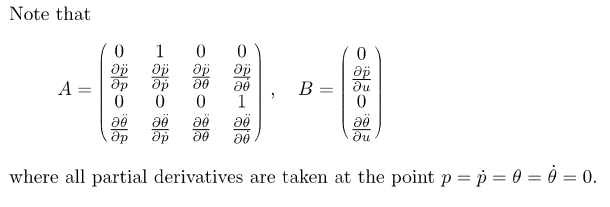

Queste matrici ci permettono di scrivere:


$$\left\lbrack \begin{array}{c}
\dot{\phi \;} \\
\ddot{\phi \;} \\
\dot{\theta \;} \\
\ddot{\theta \;} 
\end{array}\right\rbrack =A\left\lbrack \begin{array}{c}
\phi \\
\dot{\phi \;} \\
\theta \;\\
\dot{\theta \;} 
\end{array}\right\rbrack +\textrm{Bu}$$


Come prima cosa andiamo ad assegnare, al simbolo $\alpha \;,$ il valore 0.

phi2_differenziabile = subs(phi2_differenziabile,{alpha},{0});
theta2_differenziabile = subs(theta2_differenziabile,{alpha},{0});

Cerchiamo poi l'angolo in cui si ha l'equilibrio, ovvero quello in cui, con lo stato tutto posto a 0 (ovvero posizioni e velocità), si ottiene accelerazione nulla: da questo ne consegue quindi che il sistema risulta essere fermo.

NB: questo angolo è differente da 0, per la presenza dell'asta che sposta in avanti l'equilibrio del segway, che non è quindi più lungo la verticale.

NB2: abbiamo anche verificato che questo angolo *theta_equilibrio* sia uguale a 0 nel caso in cui l'asta del manubrio si trovi sopra la base (ovvero w_b = 0).

equilibri = solve(subs(theta2_differenziabile,{q_1 q_1_p q_2_p u},{0,0,0,0})==0,q_2)

La soluzione di questa equazione ritorna due posizioni di equilirbio: guardando i valori si nota che la parte complessa può essere trascurata, poichè prossima a zero.

Le due posizioni di equilibrio quindi sono

values_rad = real(equilibri); % [rad]
theta_equilibrio = values_rad(1)

Andiamo a linearizzare intorno al seguente equilibrio.

equilibrio = {0,0,theta_equilibrio,0,0,0};
%equilibrio = {0,0,0,0,0};

**Definizione della matrice A:**

A11 = 0;
A12 = 1;
A13 = 0;
A14 = 0;
A21 = subs(diff(phi2_differenziabile,q_1),  {q_1 q_1_p q_2 q_2_p u u_star},equilibrio);
A22 = subs(diff(phi2_differenziabile,q_1_p),{q_1 q_1_p q_2 q_2_p u u_star},equilibrio);
A23 = subs(diff(phi2_differenziabile,q_2),  {q_1 q_1_p q_2 q_2_p u u_star},equilibrio);
A24 = subs(diff(phi2_differenziabile,q_2_p),{q_1 q_1_p q_2 q_2_p u u_star},equilibrio);
A31 = 0;
A32 = 0;
A33 = 0;
A34 = 1;
A41 = subs(diff(theta2_differenziabile,q_1),  {q_1 q_1_p q_2 q_2_p u u_star},equilibrio);
A42 = subs(diff(theta2_differenziabile,q_1_p),{q_1 q_1_p q_2 q_2_p u u_star},equilibrio);
A43 = subs(diff(theta2_differenziabile,q_2),  {q_1 q_1_p q_2 q_2_p u u_star},equilibrio);
A44 = subs(diff(theta2_differenziabile,q_2_p),{q_1 q_1_p q_2 q_2_p u u_star},equilibrio);
A = double([A11 A12 A13 A14;A21 A22 A23 A24;A31 A32 A33 A34; A41 A42 A43 A44])

**Definizione della matrice B:**

B11 = 0;
B21 = subs(diff(phi2_differenziabile,u),{q_1 q_1_p q_2 q_2_p u u_star},equilibrio);
B31 = 0;
B41 = subs(diff(theta2_differenziabile,u),{q_1 q_1_p q_2 q_2_p u u_star},equilibrio);
B = double([B11;B21;B31;B41])

**Definizione della matrice C:**

%C = [0,0,1,0] % Riportiamo in uscita solamente l'angolo
C = eye(4); % Riportiamo in uscita tutte le variabili di stato

**Definizione della matrice D:**

D = zeros(4,1);

La procedura per la determinazione della funzione di trasferimento di un sistema, non strettamente proprio, è definita dalla relazione:


$$G\left(s\right)=C\bullet {\left(\textrm{sI}-A\right)}^{-1} \bullet B+D$$


syms s G(s);
G = (C*(s*eye(4)-A)^(-1)*B+D)